# 'plane' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### *Povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create *camera* object and put it in separate include file to save rendering time in future

pl.include_begin('camera');
    pl.camera('angle', 50, 'location', [12 12 8], 'look_at', [0 0 2], 'type', 'perspective');
pl.include_end();

#### Create *lights* objects and put them in separate include file to save rendering time in future

pl.include_begin('lights');
    pl.light('location', [12 12 8],     'color', [3 3 3], 'shadowless', true);
    pl.light('location', [-10 10 30],   'color', [3 3 3], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
pl.include_end();

#### Axis planes

pl.scene_begin('scene_file', 'plane.pov', 'image_file', 'plane.png');
    pl.include("camera");
    pl.include("lights");

    tex_plane_pink   = pl.declare("tex_plane_red",   pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.8 0.2 0.3], 'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    tex_plane_green  = pl.declare("tex_plane_green", pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.0 0.3 0.0], 'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    tex_plane_yellow = pl.declare("tex_plane_blue",  pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.3 0.3 0.0], 'finish', "phong 1 reflection {0.3 metallic 0.8}"));
             
    % Axis planes
    pl.plane('normal', [1,0,0], 'distance', 0, 'texture', tex_plane_pink);
    pl.plane('normal', [0,1,0], 'distance', 0, 'texture', tex_plane_green,  'translate', [1 0 0]);
    pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane_yellow, 'translate', [0 1 0]);

pl.scene_end();

#### Render and display

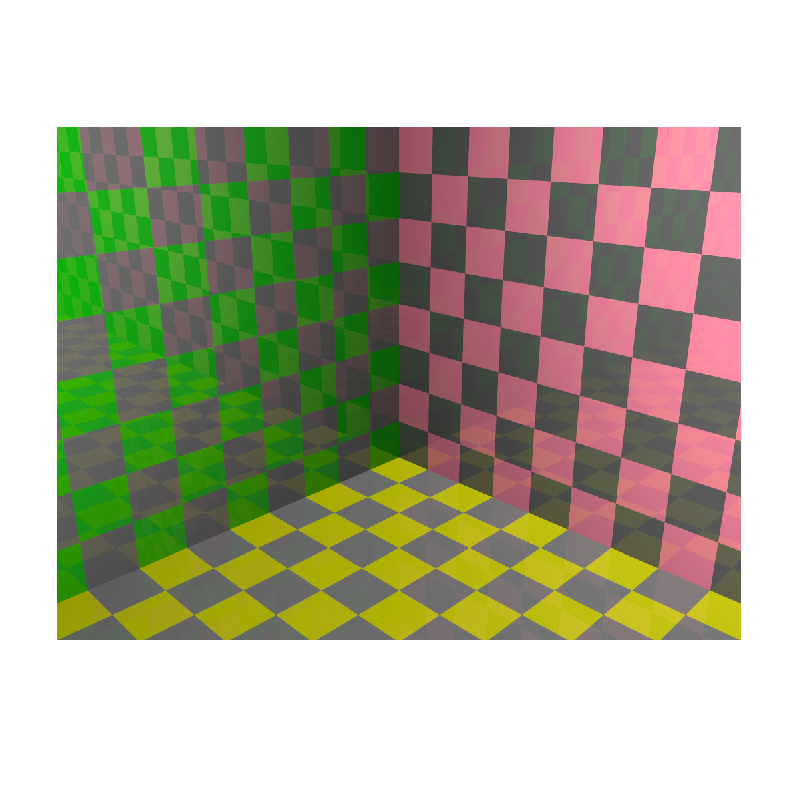

image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 3.672214 seconds.
